## **Poisson blending**

clear all;
clc;
close all;

**Loading images**

Let's first downimread images:  source and target

target = im2double(imread("ciel.png"));
src = im2double(imread("piaf.png"));

**Laplacian matrix generation**

This matrix is the size of $(rows_{src} \times column_{src})^2$. Each of its lines represents the the whole matrix with respect to a pixel of interest. The pixel of interest is set to 4, its neighbours are set to -1 and the other are set to 0.

The function discrete Laplace builds this function.

[n,m,color] = size(src);
Lap = discrete_laplace(n-2,m-2);
new_pix = zeros(n-2,m-2,color);

**Placement**

Indicate in the variable pos, the position (y,x) on the target where you want to place the upper left corner of the source image.

pos = [200 200];


for i =  1:color
% gradients computation
vpq = discrete_gradient(src(:,:,i));
target_vpq = discrete_gradient(target(pos(1):pos(1)+n-1,pos(2):pos(2)+m-1,i));

% no mixing gradients
max_grad_0 = vpq;

% gradients mixing using equation 12
max_grad_12= vpq;
idx = (abs(vpq) < abs(target_vpq));
max_grad_12(idx) = target_vpq(idx);
 
% Gradient mixing using equation 13
max_grad_13  = pixDiff(src(:,:,i),target(pos(1):pos(1)+n-1,pos(2):pos(2)+m-1,i));
 
% carefull pos = (y,x) /!\
bound = boundary(target(:,:,i),[pos(1),pos(2)],size(src));
b_0 = max_grad_0 + bound;
b_12 = max_grad_12 + bound;
b_13 = max_grad_13 + bound;
 
new_0 = Lap\b_0;
new_pix_0(:,:,i) = (reshape(new_0,[m-2,n-2]))';
 
 
new_12 = Lap\b_12;
new_pix_12(:,:,i) = (reshape(new_12,[m-2,n-2]))';
 
new_13 = Lap\b_13;
new_pix_13(:,:,i) = (reshape(new_13,[m-2,n-2]))';
end

Blending without gradient mixing 

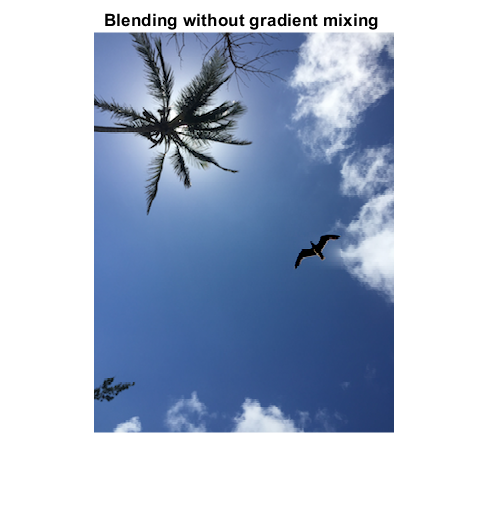

targeta_0 = target;
targeta_0(pos(1):pos(1)+n-2-1,pos(2):pos(2)+m-2-1,:) = new_pix_0;
figure;
imshow(targeta_0);
title('Blending without gradient mixing ');

Blending with gradient mixing from equation 12

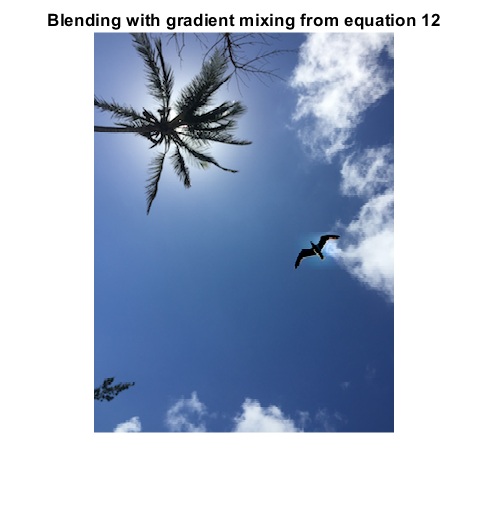

targeta_12 = target;
targeta_12(pos(1):pos(1)+n-2-1,pos(2):pos(2)+m-2-1,:) = new_pix_12;
figure;
imshow(targeta_12);
title('Blending with gradient mixing from equation 12');

Blending with gradient mixing from equation 13

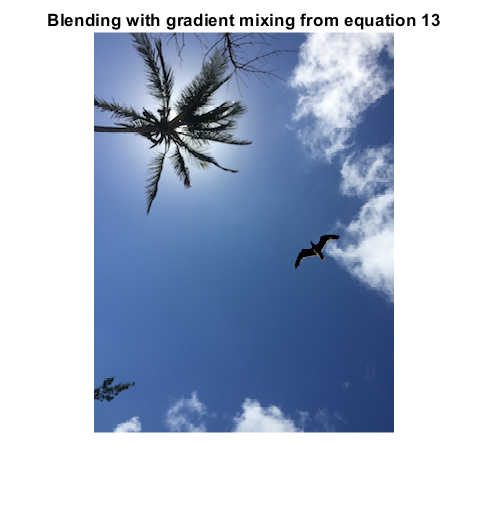

targeta_13 = target;
targeta_13(pos(1):pos(1)+n-2-1,pos(2):pos(2)+m-2-1,:) = new_pix_13;
figure;
imshow(targeta_13);
title('Blending with gradient mixing from equation 13');

No blending

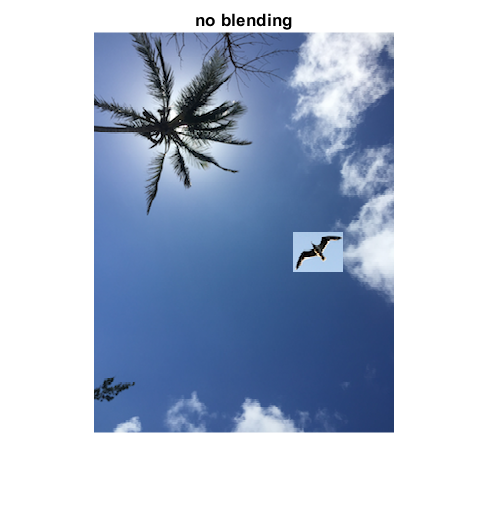

targetb = target;
targetb(pos(1):pos(1)+n-1,pos(2):pos(2)+m-1,:) = src;
figure;
imshow(targetb);
title('no blending');